# Homework 1 Computer Portion

## Load in Necessary Files

clear
load("data.mat");
load("label.mat");

## Reshape Arrays into 784 x 500/5000

reshaped_imageTrain = reshape(imageTrain, 784, 5000);
reshaped_imageTest = reshape(imageTest, 784, 500);


## Intialize Required Variables

train_dims = size(reshaped_imageTrain);
test_dims = size(reshaped_imageTest);

labelTrain = transpose(labelTrain);
labelTest = transpose(labelTest);

## Decision Rule

predicted_labels = zeros(1, test_dims(2));
min_argIndexes = zeros(1, test_dims(2));

for i = 1:test_dims(2)
    compare_imageTest = repmat(reshaped_imageTest(:, i), 1, train_dims(2));
    norm = sqrt(sum((compare_imageTest - reshaped_imageTrain) .^ 2));
    min_argIndex = find(norm == min(norm));
    min_argIndexes(i) = min_argIndex;
    predicted_labels(i) = labelTrain(min_argIndex);
end

## Error Given Class

given_classError = zeros(1, 10);
for i = 0:9
    given_Index = find(labelTest == i);
    given_Size = length(given_Index);
    pruned_labelTest = labelTest(given_Index);
    pruned_predictedLabels = predicted_labels(given_Index);
    given_classError(i + 1) = length(nonzeros(pruned_labelTest - pruned_predictedLabels)) / given_Size;
end

## Total Error

total_Error = length(nonzeros(labelTest - predicted_labels)) / test_dims(2);

## Display Misclassified Images

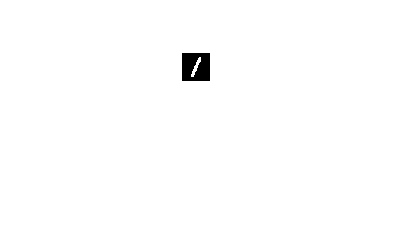

misclassified_images = find(labelTest - predicted_labels, 5);
closest_images = min_argIndexes(misclassified_images);

misclassified_filenames = ["Misclassified_Image_1", "Misclassified_Image_2", "Misclassified_Image_3", "Misclassified_Image_4", "Misclassified_Image_5"];
closest_filenames = ["Closest_Image_1", "Closest_Image_2", "Closest_Image_3", "Closest_Image_4", "Closest_Image_5"]; 

for i = 1:5
    imshow(imageTest(:, :, misclassified_images(i)));
    imshow(imageTrain(:, :, closest_images(i)));
    %imwrite(imageTest(:, :, misclassified_images(i)), misclassified_filenames(i), 'png');
    %imwrite(imageTrain(:, :, closest_images(i)), closest_filenames(i), 'png');
end